clear all; close all; clc

N = 1e5;   
dz = 2;

dz = 2


X = rand(N, 1);


Y = zeros(size(X));
Y(X <= 0.5) = -1 + sqrt(2 * X(X <= 0.5));  
Y(X > 0.5) = 1 - sqrt(2 - 2 * X(X > 0.5)); 
Y = real(Y);

sum_Y = 0;
for i = 1:N
    sum_Y = sum_Y + Y(i);
end
mean_Y = sum_Y / N

mean_Y = -0.0014


sum_var = 0;
for i = 1:N
    sum_var = sum_var + (Y(i) - mean_Y)^2;
end
variance_Y = sum_var / (N-1)

variance_Y = 0.1672

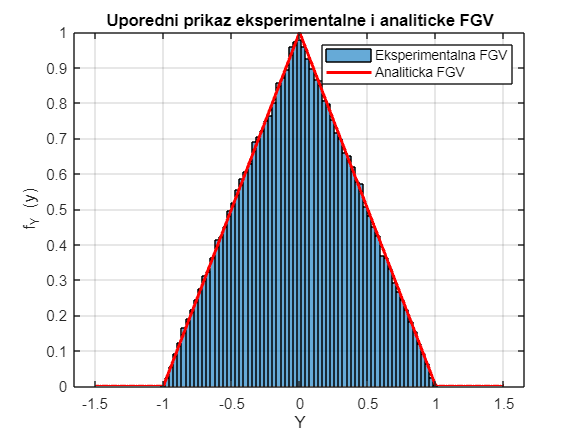


figure;
edges = linspace(-1.5, 1.5, 100);  
histogram(Y, edges, 'Normalization', 'pdf'); 
hold on;

y_vals = linspace(-1.5, 1.5, 1000);
f_Y = @(y) max(0, 1 - abs(y));  
plot(y_vals, f_Y(y_vals), 'r-', 'LineWidth', 2);


xlabel('Y');
ylabel('f_Y (y)');
legend('Eksperimentalna FGV', 'Analiticka FGV');
title('Uporedni prikaz eksperimentalne i analiticke FGV');
grid on;
hold off;

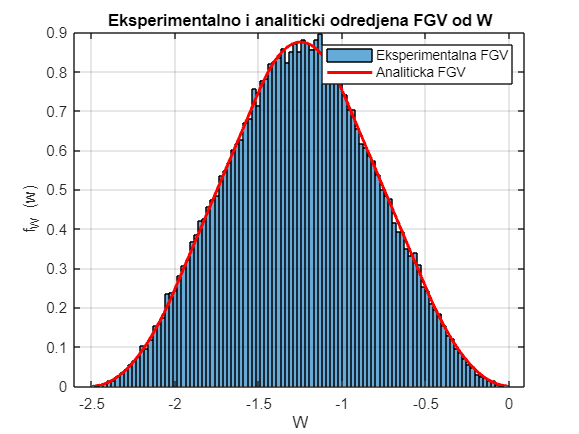



Z = -1.5 + (1.5 - 1) * rand(N, 1);

% Compute W = Y + Z
W = Y + Z;

% Plot the histogram of W
figure;
edges = linspace(min(W), max(W), 100);  
histogram(W, edges, 'Normalization', 'pdf');
hold on;

f_Z = @(z) (z >= -1.5 & z <= -1) * dz;  % f_Z(z) = 2 for z in [-1.5, -1]

% Define the range for W
w_vals = linspace(-2.5, 0, 1000);  % Range of W
f_W = zeros(size(w_vals));          % Initialize PDF of W

% Numerical convolution
for i = 1:length(w_vals)
    w = w_vals(i);
    integrand = @(y) f_Y(y) .* f_Z(w - y);  % Convolution formula
    f_W(i) = integral(integrand, -1, 1, 'ArrayValued', true); % Limits for Y
end

plot(w_vals, f_W, 'r-', 'LineWidth', 2);

xlabel('W');
ylabel('f_W (w)');
legend('Eksperimentalna FGV', 'Analiticka FGV');
title('Eksperimentalno i analiticki odredjena FGV od W');
grid on;
hold off;